## Time–Frequency Analysis of Environmental Sounds Using MATLAB

Haoliang Xiong

Student ID: 500051742

Date: 2 September 2026

### 1. Objective

This report investigates the time–frequency characteristics of three environmental sounds—rain, dog bark and clock tick—using MATLAB. Time-frequency representations are widely used to characterise environmental sounds with different temporal and spectral properties [3]. In this report, time-domain waveforms, Fourier spectra and Short-Time Fourier Transform (STFT) spectrograms are used to compare sustained, non-stationary and transient sound events. The effect of STFT window length on the trade-off between temporal and frequency resolution is also examined, with particular attention to the transient structure of clock-tick signals.

### 2. Background

Environmental sounds can contain both stationary and rapidly changing components, so a single representation is often insufficient to describe their behaviour. A Fourier transform represents the overall frequency content of a signal, but it does not indicate when individual frequency components occur [2].


$$X[k]=\sum_{n=0}^{N-1}x[n]e^{-j2\pi kn/N}$$


where x[n] is the discrete-time signal, N is the number of samples, k is the frequency-bin index, and X[k] is the corresponding DFT coefficient.

This limitation is important for non-stationary sounds such as dog barks and short transient events such as clock ticks. The Short-Time Fourier Transform (STFT) addresses this problem by dividing the signal into overlapping frames, applying a window to each frame, and computing a Fourier transform for each short-time segment [4].


$$X[m,k]=\sum_{r=0}^{L-1}x[mH+r]w[r]e^{-j2\pi kr/N}$$


where m is the frame index, k is the FFT-bin index, L is the window length, H is the hop size, N is the FFT size, and w[r] is the analysis window.

The resulting spectrogram shows how spectral energy changes over time. In the STFT, window length controls the main time–frequency resolution trade-off: shorter windows provide better temporal localisation but poorer frequency resolution, while longer windows improve frequency resolution but smear fast temporal changes [5].

### 3. Methodology and Implementation

#### 3.1 Audio Samples

Three five-second environmental audio recordings were selected from the ESC-50 dataset for analysis [1]. The selected categories were rain, dog bark and clock tick. The original ESC-50 files were `1-17367-A-10.wav` (rain), `1-30226-A-0.wav` (dog) and `1-21934-A-38.wav` (clock tick). For clearer file handling in MATLAB, copies of these recordings were stored in the report directory as `rain.wav`, `dog_bark.wav` and `clock_tick.wav`, respectively. The original audio content was not modified. These three categories were selected to provide contrasting environmental sound examples for comparing time-domain, frequency-domain and time–frequency representations.

#### 3.2 Processing Pipeline

As shown in Figure 1, the analysis followed a consistent processing pipeline for all three recordings. Each audio file was first loaded and checked for sampling rate, duration and number of channels. The signals were then examined in the time domain, transformed into the frequency domain using the FFT, and further analysed using STFT spectrograms. Finally, different STFT window lengths were compared using the clock-tick recording to investigate the trade-off between temporal and frequency resolution.

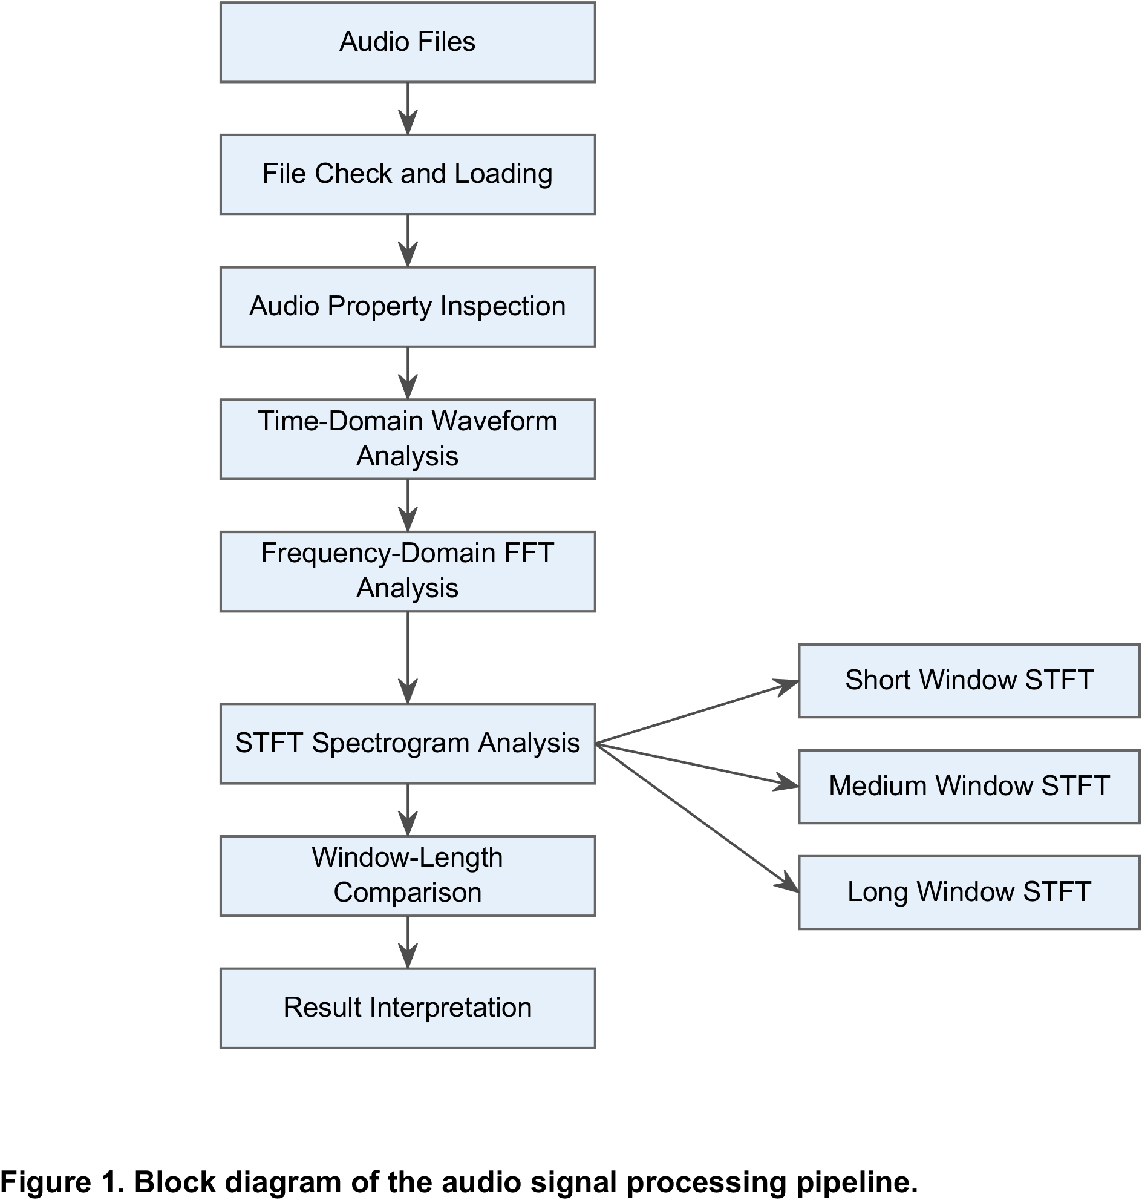

#### 3.3 Analysis Parameters

A periodic Hann window was selected for the STFT analysis to reduce spectral leakage at frame boundaries. The baseline STFT used a window length of 2048 samples, a hop size of 512 samples and an FFT size of 2048 samples. 


$$T_w=\frac{L}{f_s},\qquad T_h=\frac{H}{f_s}$$


With fs = 44.1 kHz, L = 2048 and H = 512, the baseline window duration was approximately 46.44 ms and the hop duration was approximately 11.61 ms.

These settings correspond to 75% overlap between adjacent frames. To investigate the time–frequency resolution trade-off, the clock-tick signal was additionally analysed using three window lengths: 512, 2048 and 4096 samples. The hop size was set to one quarter of the window length in each case, maintaining 75% overlap. 


$$\mathrm{Overlap}=1-\frac{H}{L}$$


For H = 512 and L = 2048, the overlap ratio is 1 − 512/2048 = 0.75, or 75%.

In the visual comparison, the FFT size was set equal to each window length and the hop size was set to one quarter of that length, so the plots compare three complete STFT configurations. A separate quantitative experiment therefore fixed NFFT at 4096 and the hop size at 128 samples to isolate the effect of window length more clearly.

### 4. Code and Results

#### 4.1 Signal Loading and Validation

The three selected ESC-50 recordings were first loaded and checked before further analysis. The validation stage confirms that the required files are available and records their sampling rate, duration and channel configuration. This avoids assuming signal properties before processing and supports reproducibility of the subsequent analysis.

%% Environment Setup

clear;
close all;
clc;

%% Define Audio File Paths

rainFile = fullfile('audio', 'rain.wav');
dogFile  = fullfile('audio', 'dog_bark.wav');
tickFile = fullfile('audio', 'clock_tick.wav');

assert(isfile(rainFile), 'rain.wav was not found.');
assert(isfile(dogFile), 'dog_bark.wav was not found.');
assert(isfile(tickFile), 'clock_tick.wav was not found.');

disp('All three audio files were found successfully.');

All three audio files were found successfully.


%% Load Audio Samples

[rain, fsRain] = audioread(rainFile);
[dog, fsDog]   = audioread(dogFile);
[tick, fsTick] = audioread(tickFile);

%% Inspect Original Audio Properties

infoRain = audioinfo(rainFile);
infoDog  = audioinfo(dogFile);
infoTick = audioinfo(tickFile);

fprintf('Rain       : Fs = %d Hz, Channels = %d, Duration = %.3f s\n', ...
    infoRain.SampleRate, infoRain.NumChannels, infoRain.Duration);

Rain       : Fs = 44100 Hz, Channels = 1, Duration = 5.000 s



fprintf('Dog bark   : Fs = %d Hz, Channels = %d, Duration = %.3f s\n', ...
    infoDog.SampleRate, infoDog.NumChannels, infoDog.Duration);

Dog bark   : Fs = 44100 Hz, Channels = 1, Duration = 5.000 s



fprintf('Clock tick : Fs = %d Hz, Channels = %d, Duration = %.3f s\n', ...
    infoTick.SampleRate, infoTick.NumChannels, infoTick.Duration);

Clock tick : Fs = 44100 Hz, Channels = 1, Duration = 5.000 s


%% Validate Consistent Audio Properties

assert(fsRain == fsDog && fsDog == fsTick, ...
    'The three audio samples do not have the same sampling rate.');

assert(infoRain.NumChannels == 1 && ...
       infoDog.NumChannels == 1 && ...
       infoTick.NumChannels == 1, ...
    'One or more audio files are not mono.');

fs = fsRain;

fprintf('Validation complete: all files are mono and sampled at %d Hz.\n', fs);

Validation complete: all files are mono and sampled at 44100 Hz.


%% Create Audio Summary Table

soundName = ["Rain"; "Dog bark"; "Clock tick"];

sampleRate = [
    fsRain;
    fsDog;
    fsTick
];

duration = [
    length(rain) / fsRain;
    length(dog) / fsDog;
    length(tick) / fsTick
];

numSamples = [
    length(rain);
    length(dog);
    length(tick)
];

peakAmplitude = [
    max(abs(rain));
    max(abs(dog));
    max(abs(tick))
];

rmsAmplitude = [
    sqrt(mean(rain.^2));
    sqrt(mean(dog.^2));
    sqrt(mean(tick.^2))
];

audioSummary = table( ...
    soundName, ...
    sampleRate, ...
    duration, ...
    numSamples, ...
    peakAmplitude, ...
    rmsAmplitude, ...
    'VariableNames', ...
    {'Sound','SampleRate_Hz','Duration_s','Samples', ...
     'PeakAmplitude','RMSAmplitude'} ...
);

disp(audioSummary);

       Sound        SampleRate_Hz    Duration_s     Samples     PeakAmplitude    RMSAmplitude
    ____________    _____________    __________    _________    _____________    ____________

    "Rain"              44100            5         2.205e+05       0.66357         0.087673  
    "Dog bark"          44100            5         2.205e+05       0.44791         0.036558  
    "Clock tick"        44100            5         2.205e+05       0.36551         0.027694  



Table 1. Summary statistics of the three selected audio recordings.

#### 4.2 Time-Domain Analysis

The waveform of each recording was plotted over the full five-second duration to compare its temporal amplitude structure. This representation is useful for identifying sustained activity, isolated events and transient behaviour before examining the frequency content.

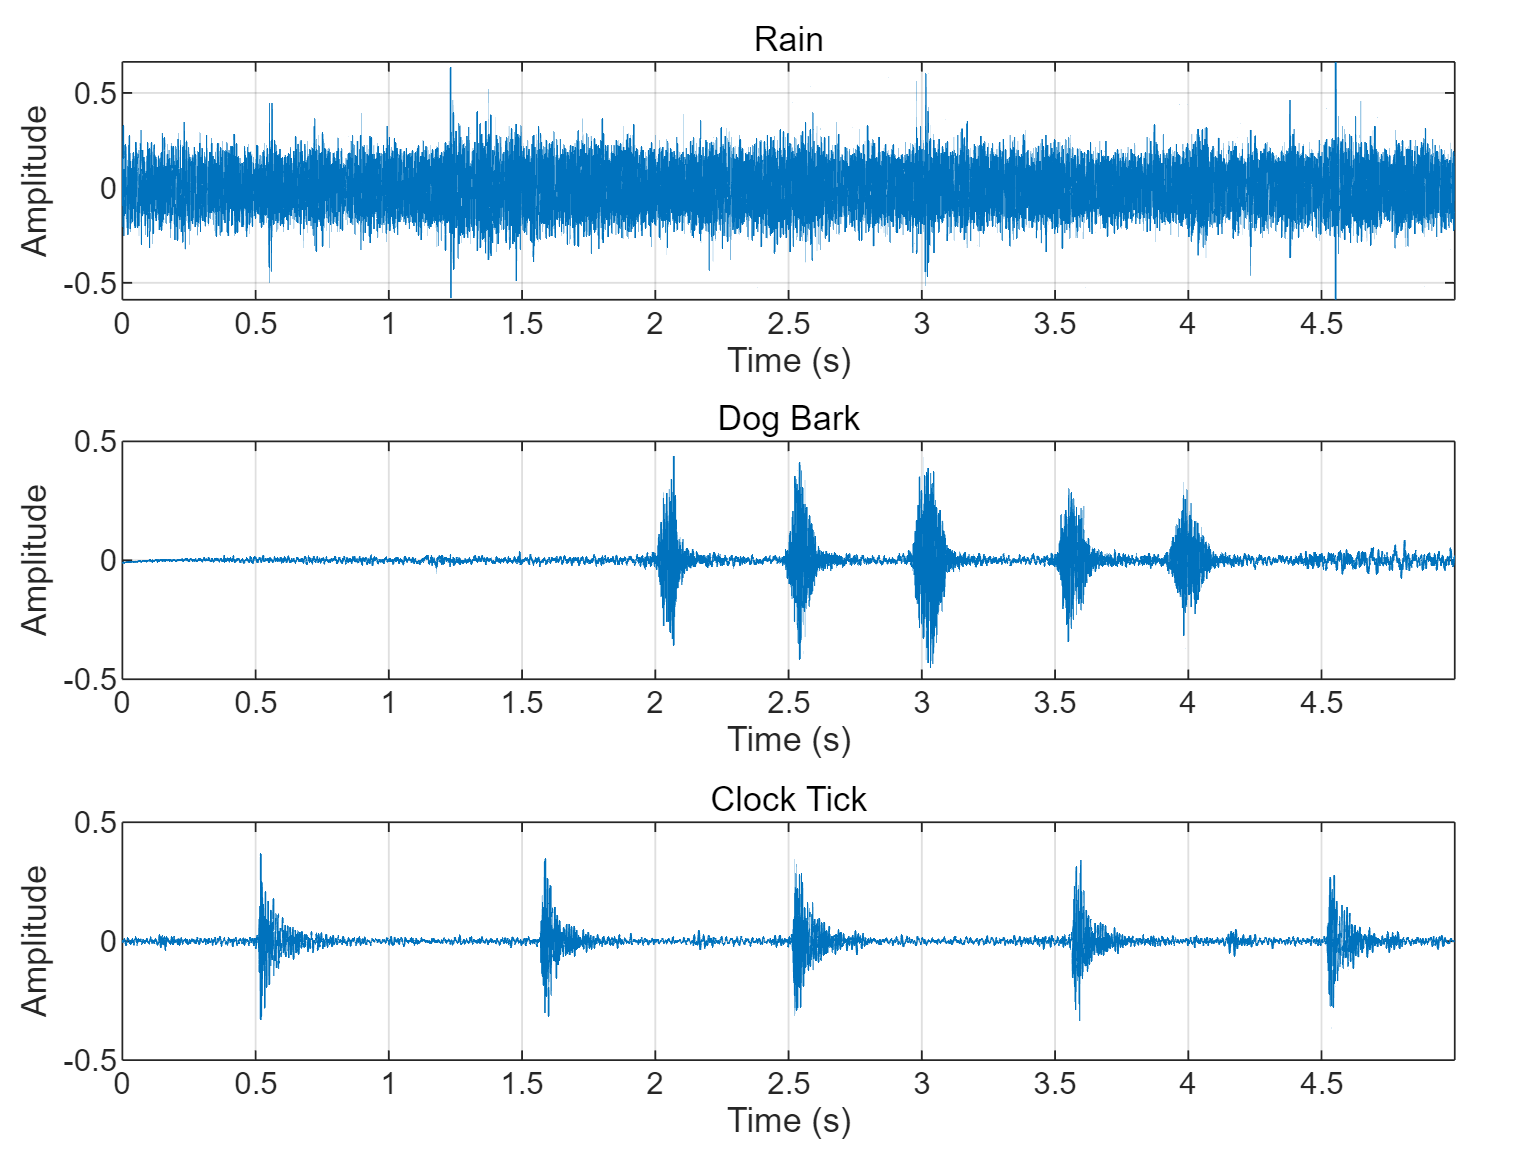

%% Create Time Axes

tRain = (0:length(rain)-1) / fsRain;
tDog  = (0:length(dog)-1) / fsDog;
tTick = (0:length(tick)-1) / fsTick;

%% Time-Domain Waveform Comparison

figure('Name', 'Environmental Sound Waveforms');

tiledlayout(3,1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

nexttile;
plot(tRain, rain);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Rain');
xlim([0 tRain(end)]);

nexttile;
plot(tDog, dog);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Dog Bark');
xlim([0 tDog(end)]);

nexttile;
plot(tTick, tick);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Clock Tick');
xlim([0 tTick(end)]);

Figure 2. Time-domain waveforms of the rain, dog-bark and clock-tick recordings.

Figure 2. Time-domain waveforms of rain, dog bark and clock tick. As shown in Figure 2, the rain waveform remains active throughout the recording, while the dog bark and clock tick appear as shorter, separated events. The rain signal contains continuous activity throughout the five-second recording, with no extended silent intervals, which is consistent with a sustained noise-like sound. In contrast, the dog-bark recording contains several distinct high-energy events separated by lower-amplitude regions. The clock-tick signal shows even shorter and more clearly localised transient events occurring at approximately regular intervals. These differences demonstrate that the time-domain waveform is effective for identifying when acoustic events occur and how their amplitudes vary over time, but it does not directly reveal the frequency components that form each sound.

#### 4.3 Frequency-Domain Analysis

A Fourier analysis was next used to compare the overall spectral content of the three recordings. The Fast Fourier Transform (FFT) converts each complete five-second waveform from the time domain to the frequency domain. This representation can reveal how signal energy is distributed across frequency, but because the FFT is applied to the entire recording, it does not preserve information about when individual sound events occur.


$$M_{\mathrm{dB}}[k]=20\log_{10}\left(\frac{|X[k]|}{\max_k|X[k]|}\right)$$


Each magnitude spectrum was normalised by its own maximum value before conversion to decibels, so the largest spectral component of each recording is shown at 0 dB. This allows comparison of spectral shape rather than absolute recording amplitude.

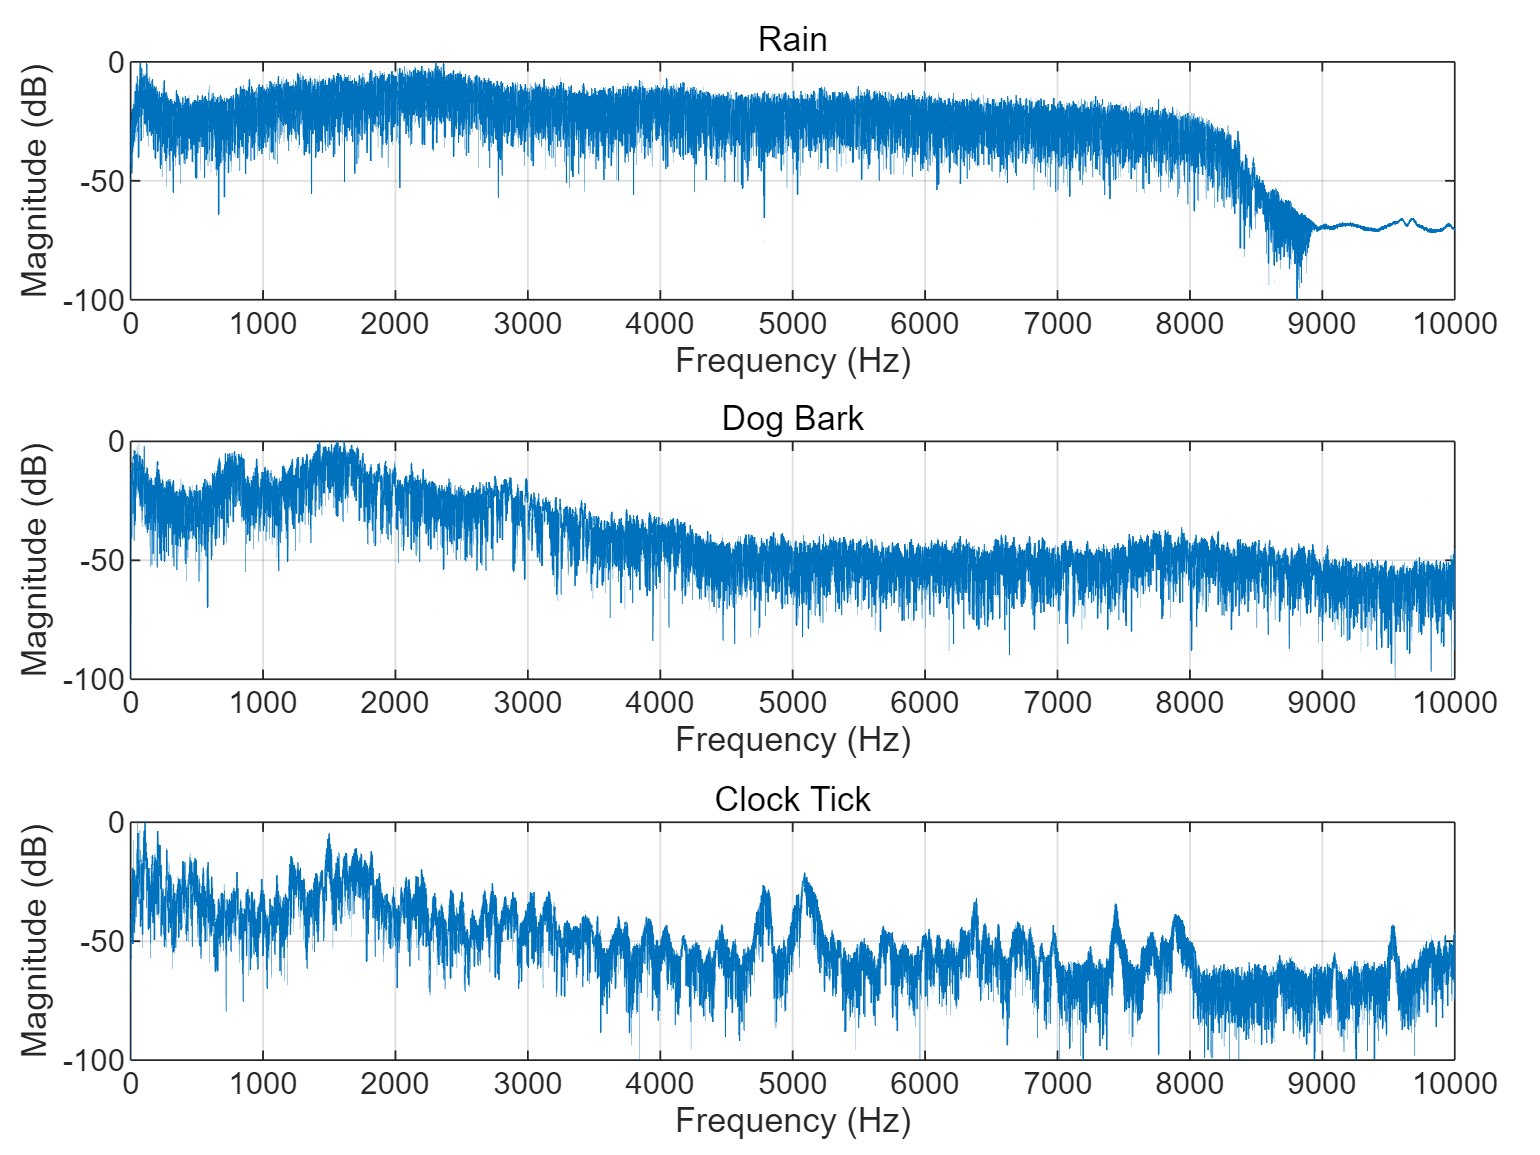

%% Compute Single-Sided FFT Spectra

% Remove the small DC component before spectral analysis.
rainFFTInput = rain - mean(rain);
dogFFTInput  = dog  - mean(dog);
tickFFTInput = tick - mean(tick);

% All three recordings have the same length and sampling rate.
N = length(rain);

% Frequency axis for the single-sided spectrum.
f = (0:floor(N/2)) * fs / N;


%% Rain Spectrum

YRain = fft(rainFFTInput);

magRain = abs(YRain / N);
magRain = magRain(1:floor(N/2)+1);

magRain(2:end-1) = 2 * magRain(2:end-1);

rainSpectrum_dB = 20 * log10( ...
    magRain / max(magRain) + eps ...
);


%% Dog Bark Spectrum

YDog = fft(dogFFTInput);

magDog = abs(YDog / N);
magDog = magDog(1:floor(N/2)+1);

magDog(2:end-1) = 2 * magDog(2:end-1);

dogSpectrum_dB = 20 * log10( ...
    magDog / max(magDog) + eps ...
);


%% Clock Tick Spectrum

YTick = fft(tickFFTInput);

magTick = abs(YTick / N);
magTick = magTick(1:floor(N/2)+1);

magTick(2:end-1) = 2 * magTick(2:end-1);

tickSpectrum_dB = 20 * log10( ...
    magTick / max(magTick) + eps ...
);


%% Frequency-Domain Comparison

figure('Name', 'Environmental Sound FFT Spectra');

tiledlayout(3,1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

nexttile;
plot(f, rainSpectrum_dB);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Rain');
xlim([0 10000]);
ylim([-100 0]);

nexttile;
plot(f, dogSpectrum_dB);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Dog Bark');
xlim([0 10000]);
ylim([-100 0]);

nexttile;
plot(f, tickSpectrum_dB);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Clock Tick');
xlim([0 10000]);
ylim([-100 0]);

Figure 3. Normalised single-sided FFT magnitude spectra of the three selected sounds.

Figure 3. Normalised FFT magnitude spectra of the three selected sounds. As shown in Figure 3, rain has a broad continuous spectrum, whereas dog bark and clock tick exhibit more structured frequency distributions. Rain shows a relatively broad and continuous spectral distribution over the lower and mid-frequency range, followed by a pronounced reduction at higher frequencies. The dog-bark signal is dominated by lower-frequency energy and shows a gradual decrease in magnitude toward higher frequencies, with a less uniform spectral shape than rain. The clock-tick recording also contains broadband frequency content, together with several more distinct spectral peaks. This relatively wide spectral distribution is consistent with its short transient events observed in the time domain. However, because each FFT was computed over the complete five-second recording, the spectra do not indicate when the bark or tick events occur. A time–frequency representation is therefore required.

#### 4.4 STFT Analysis

The FFT provides the overall spectral content of each recording but removes the temporal location of individual events. To preserve both time and frequency information, the Short-Time Fourier Transform (STFT) was applied to the three signals. Each recording was divided into overlapping short-time frames, multiplied by a periodic Hann window and transformed using the FFT. The baseline analysis used a window length of 2048 samples, a hop size of 512 samples and an FFT size of 2048 samples.

%% Baseline STFT Parameters

winLength = 2048;
hopSize   = 512;
noverlap  = winLength - hopSize;
nfft      = 2048;

win = hann(winLength, 'periodic');

windowDuration_ms = winLength / fs * 1000;
hopDuration_ms = hopSize / fs * 1000;

fprintf('Window duration = %.2f ms\n', windowDuration_ms);

Window duration = 46.44 ms


fprintf('Hop duration    = %.2f ms\n', hopDuration_ms);

Hop duration    = 11.61 ms


fprintf('Overlap         = %.1f %%\n', 100 * noverlap / winLength);

Overlap         = 75.0 %


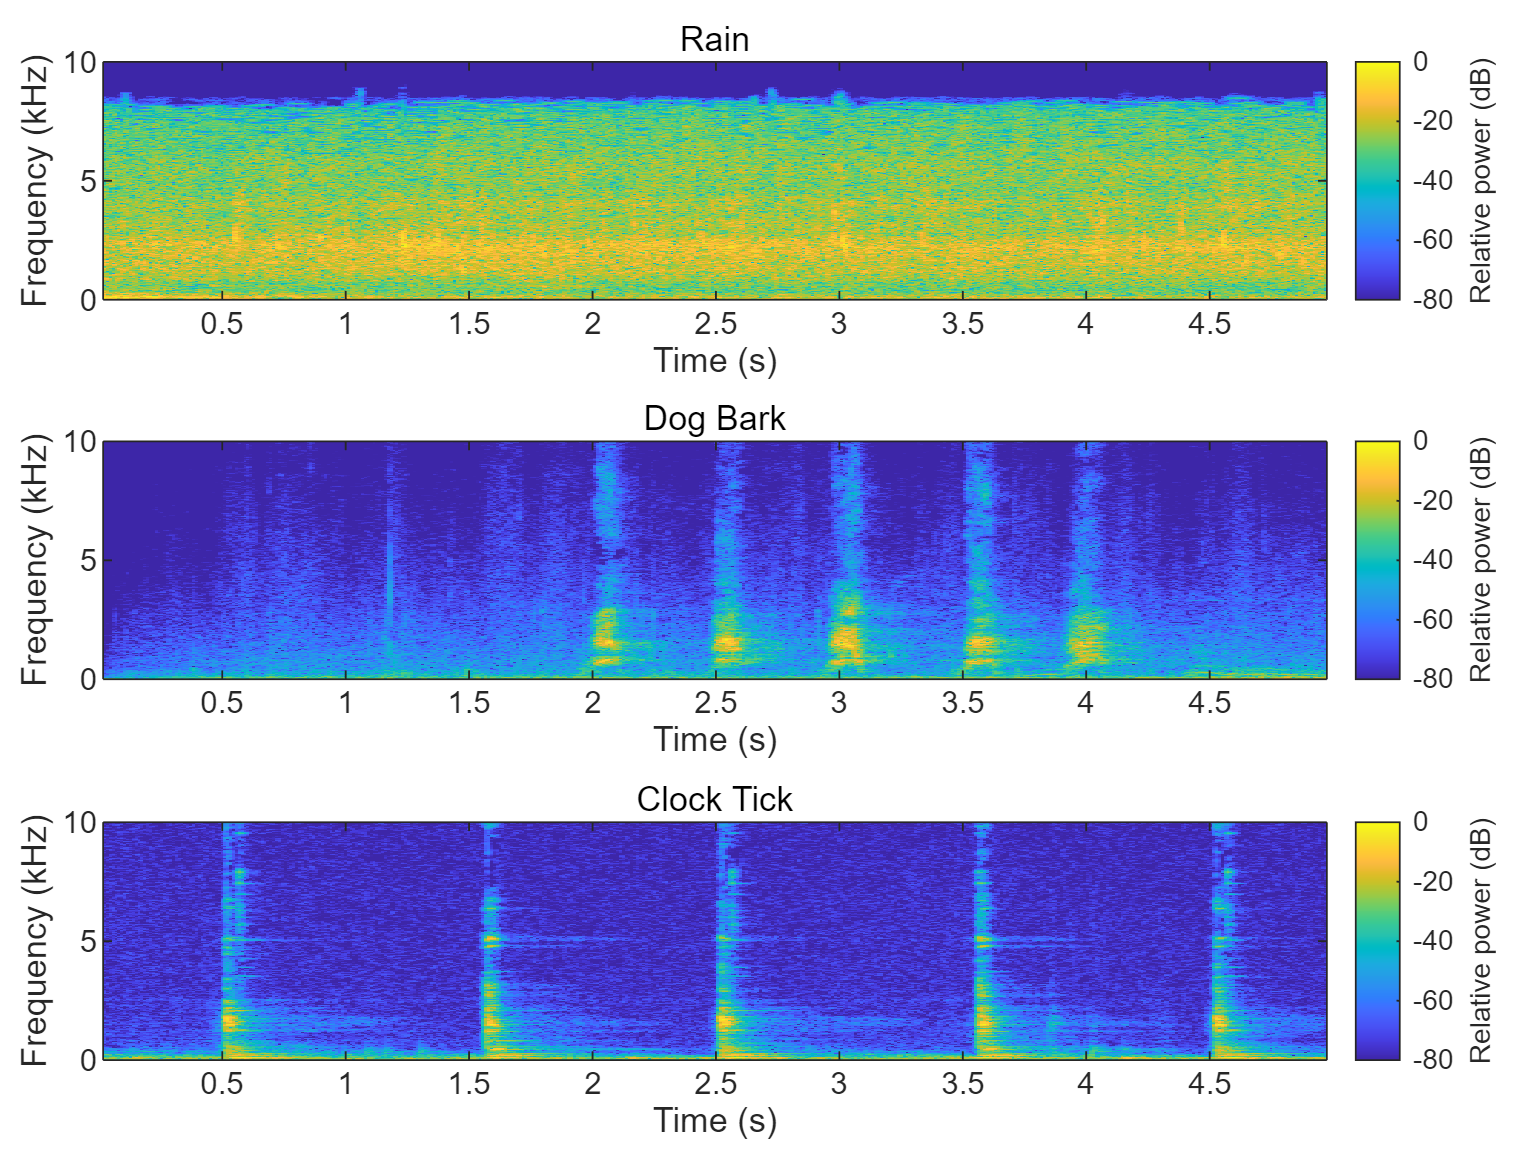

%% Compute Baseline STFTs

[~, fRain, tRainSTFT, pRain] = spectrogram( ...
    rain, win, noverlap, nfft, fs);

[~, fDog, tDogSTFT, pDog] = spectrogram( ...
    dog, win, noverlap, nfft, fs);

[~, fTick, tTickSTFT, pTick] = spectrogram( ...
    tick, win, noverlap, nfft, fs);
%% Convert STFT Power to Normalised dB

pRain_dB = 10 * log10(pRain + eps);
pDog_dB  = 10 * log10(pDog + eps);
pTick_dB = 10 * log10(pTick + eps);

pRain_dB = pRain_dB - max(pRain_dB(:));
pDog_dB  = pDog_dB  - max(pDog_dB(:));
pTick_dB = pTick_dB - max(pTick_dB(:));


%% Baseline STFT Comparison

figure('Name', 'Environmental Sound STFT Comparison');

tiledlayout(3,1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

nexttile;
imagesc(tRainSTFT, fRain/1000, pRain_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Rain');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tDogSTFT, fDog/1000, pDog_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Dog Bark');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tTickSTFT, fTick/1000, pTick_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Clock Tick');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

Figure 4. Baseline STFT spectrograms of the three selected sounds using a 2048-sample Hann window.

Figure 4. Baseline STFT spectrograms using a 2048-sample Hann window. Figure 4 shows clear differences in the time–frequency behaviour of the three environmental sounds. Rain exhibits relatively continuous spectral energy throughout the full recording, with most visible energy concentrated below approximately 8–9 kHz. This agrees with its sustained time-domain waveform. In contrast, the dog-bark spectrogram contains several distinct broadband events, particularly during the second half of the recording, with stronger energy concentrated at lower frequencies. The clock-tick spectrogram shows narrow, regularly spaced transient events at approximately 0.5, 1.6, 2.5, 3.6 and 4.5 seconds. Each tick extends across a relatively broad frequency range. Unlike the whole-recording FFT, the STFT therefore preserves the temporal locations of these spectral events while also showing their frequency content.

#### 4.5 Effect of Window Length on Time–Frequency Resolution

The clock-tick recording was selected to investigate the effect of STFT window length because its short transient events provide clear temporal reference points. Three periodic Hann windows of 512, 2048 and 4096 samples were compared. The hop size was maintained at one quarter of the corresponding window length, giving 75% overlap in all cases. This experiment examines the trade-off between temporal localisation and frequency resolution.

%% Window-Length Comparison Parameters

shortL = 512;
mediumL = 2048;
longL = 4096;

shortH = shortL / 4;
mediumH = mediumL / 4;
longH = longL / 4;

shortOverlap = shortL - shortH;
mediumOverlap = mediumL - mediumH;
longOverlap = longL - longH;

shortWin = hann(shortL, 'periodic');
mediumWin = hann(mediumL, 'periodic');
longWin = hann(longL, 'periodic');

fprintf('Short window  : %.2f ms\n', shortL/fs*1000);

Short window  : 11.61 ms


fprintf('Medium window : %.2f ms\n', mediumL/fs*1000);

Medium window : 46.44 ms


fprintf('Long window   : %.2f ms\n', longL/fs*1000);

Long window   : 92.88 ms


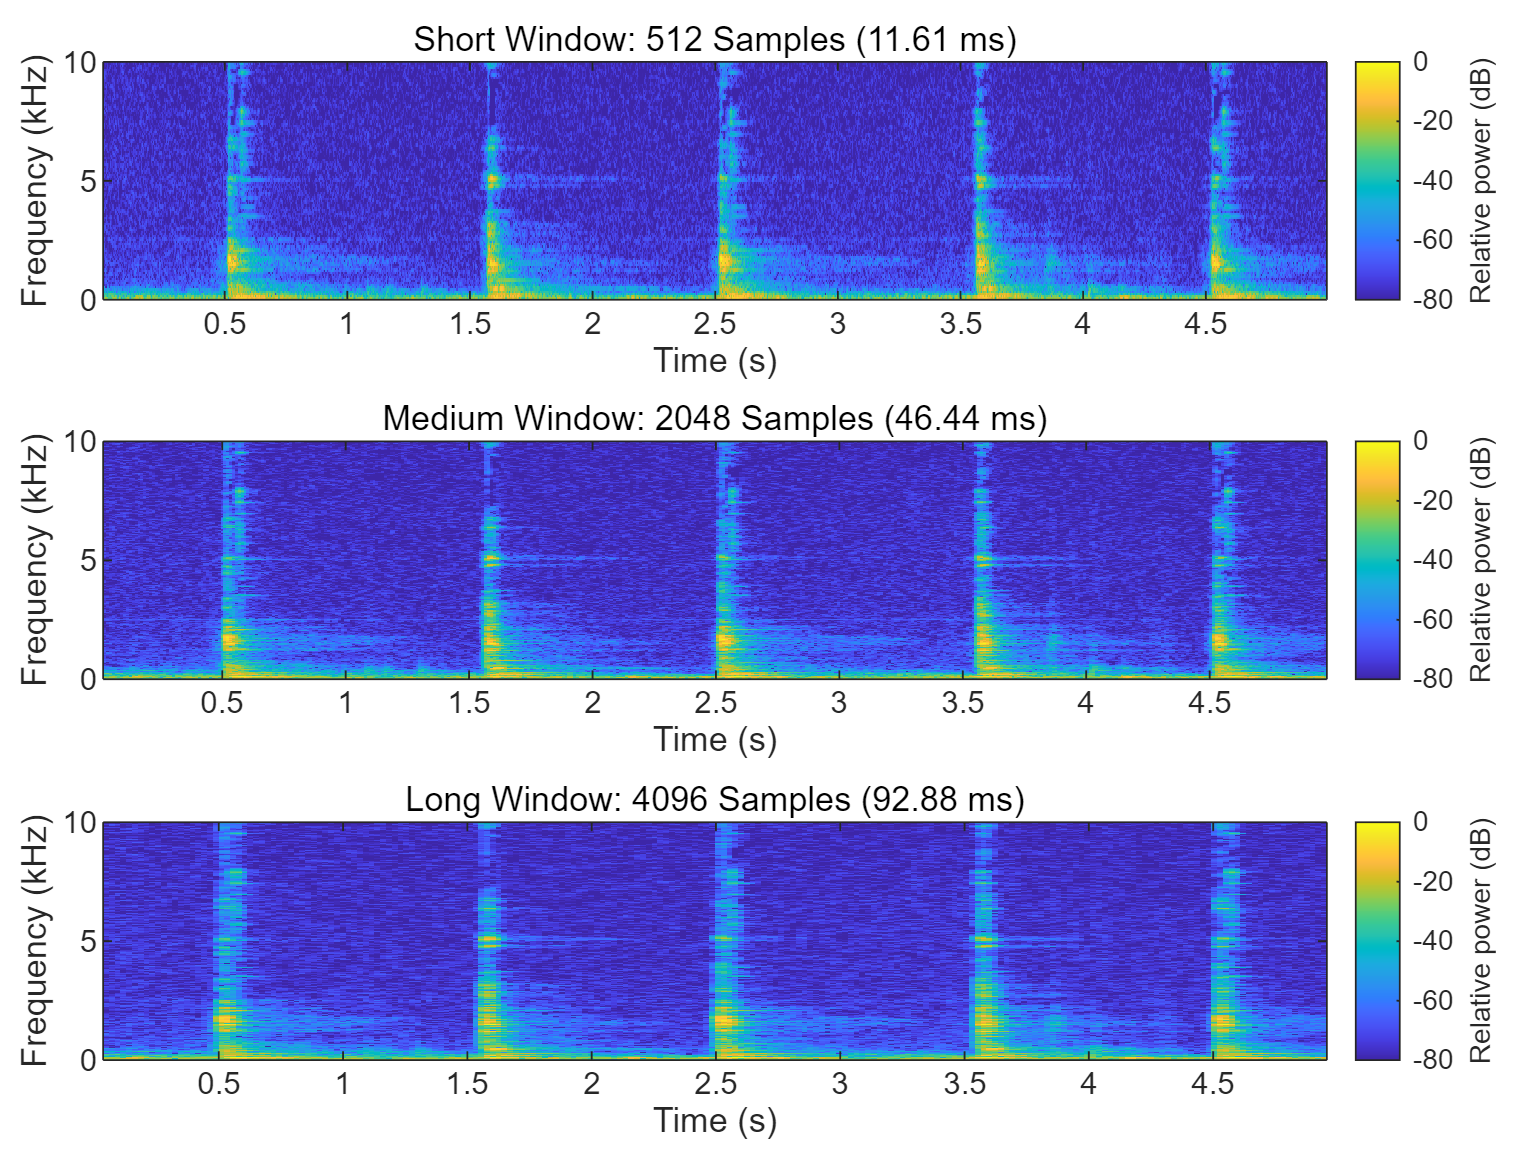

%% Compute Clock-Tick STFTs with Different Window Lengths

[~, fShort, tShort, pShort] = spectrogram( ...
    tick, shortWin, shortOverlap, shortL, fs);

[~, fMedium, tMedium, pMedium] = spectrogram( ...
    tick, mediumWin, mediumOverlap, mediumL, fs);

[~, fLong, tLong, pLong] = spectrogram( ...
    tick, longWin, longOverlap, longL, fs);

%% Convert to Normalised dB

pShort_dB = 10 * log10(pShort + eps);
pMedium_dB = 10 * log10(pMedium + eps);
pLong_dB = 10 * log10(pLong + eps);

pShort_dB = pShort_dB - max(pShort_dB(:));
pMedium_dB = pMedium_dB - max(pMedium_dB(:));
pLong_dB = pLong_dB - max(pLong_dB(:));

%% Clock-Tick Window-Length Comparison

figure('Name', 'Effect of STFT Window Length');

tiledlayout(3,1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

nexttile;
imagesc(tShort, fShort/1000, pShort_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Short Window: 512 Samples (11.61 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tMedium, fMedium/1000, pMedium_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Medium Window: 2048 Samples (46.44 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tLong, fLong/1000, pLong_dB);
axis xy;
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Long Window: 4096 Samples (92.88 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

Figure 5. Comparison of clock-tick STFT spectrograms using Hann windows of 512, 2048 and 4096 samples.

Figure 5. Comparison of clock-tick STFT spectrograms using three window lengths. As shown in Figure 5, the main clock-tick events stay at similar temporal locations, but their time–frequency representations change with analysis-window length. With the 512-sample window, each transient is more tightly localised in time, while the frequency structure appears comparatively coarse. Increasing the window length to 2048 and 4096 samples causes the transient events to spread over a wider time interval, while narrow spectral structures become more clearly defined. The result is consistent with the expected STFT time–frequency trade-off: shorter windows favour temporal localisation, whereas longer windows provide finer frequency sampling at the cost of temporal precision.

%% Window-Length Parameter Summary

windowSamples = [
    shortL;
    mediumL;
    longL
];

hopSamples = [
    shortH;
    mediumH;
    longH
];

windowDuration_ms = windowSamples / fs * 1000;
hopDuration_ms = hopSamples / fs * 1000;

fftBinSpacing_Hz = fs ./ windowSamples;

windowLabel = [
    "Short";
    "Medium";
    "Long"
];

windowSummary = table( ...
    windowLabel, ...
    windowSamples, ...
    hopSamples, ...
    windowDuration_ms, ...
    fftBinSpacing_Hz, ...
    'VariableNames', ...
    {'Window','Length_samples','Hop_samples', ...
     'Duration_ms','FFTBinSpacing_Hz'} ...
);

disp(windowSummary);

     Window     Length_samples    Hop_samples    Duration_ms    FFTBinSpacing_Hz
    ________    ______________    ___________    ___________    ________________

    "Short"           512             128           11.61            86.133     
    "Medium"         2048             512           46.44            21.533     
    "Long"           4096            1024           92.88            10.767     



Table 2. STFT parameter settings for the three window lengths.

Increasing the window length from 512 to 4096 samples increased the analysis duration from approximately 11.61 ms to 92.88 ms. At the same time, the FFT-bin spacing decreased from approximately 86.13 Hz to 10.77 Hz. These numerical changes help explain the visual behaviour of the spectrograms: a longer analysis window covers a larger interval of the transient signal but samples the frequency axis more densely.

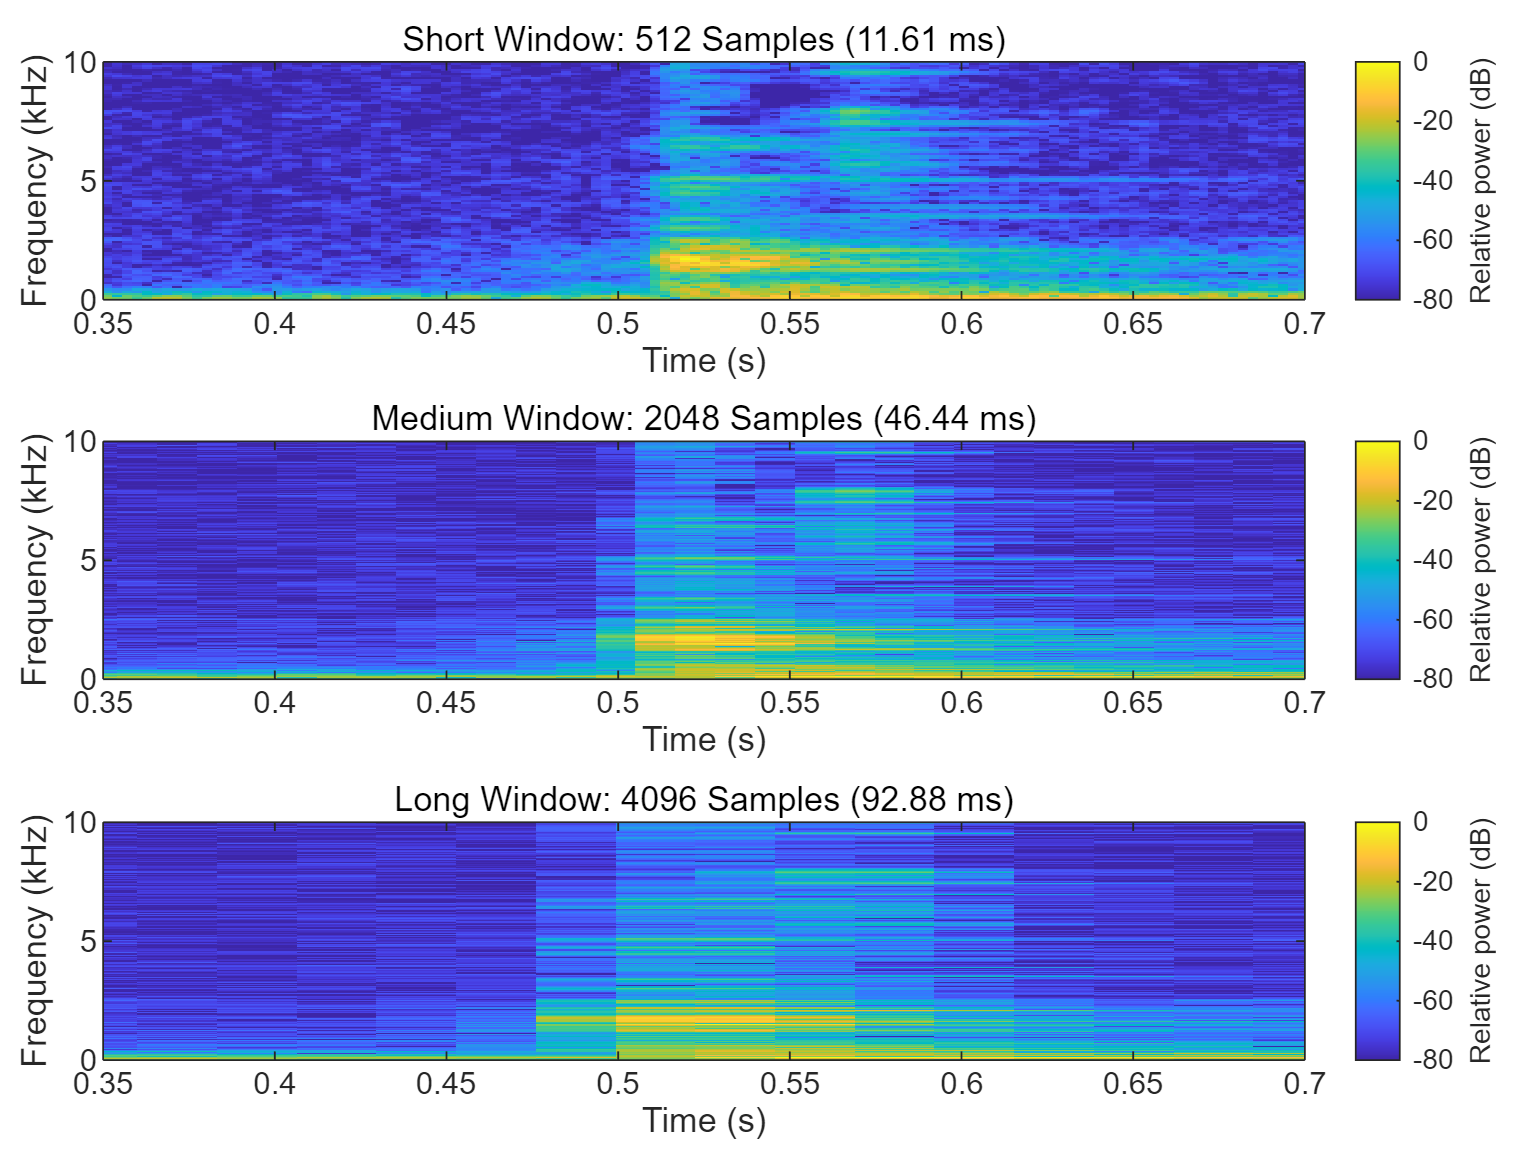

%% Zoomed Window-Length Comparison Around One Clock Tick

figure('Name', 'Zoomed STFT Window-Length Comparison');

tiledlayout(3,1, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

nexttile;
imagesc(tShort, fShort/1000, pShort_dB);
axis xy;
xlim([0.35 0.70]);
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Short Window: 512 Samples (11.61 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tMedium, fMedium/1000, pMedium_dB);
axis xy;
xlim([0.35 0.70]);
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Medium Window: 2048 Samples (46.44 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

nexttile;
imagesc(tLong, fLong/1000, pLong_dB);
axis xy;
xlim([0.35 0.70]);
ylim([0 10]);
clim([-80 0]);
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('Long Window: 4096 Samples (92.88 ms)');
cb = colorbar; cb.Label.String = 'Relative power (dB)';

Figure 6. Zoomed comparison of a single clock tick using Hann windows of 512, 2048 and 4096 samples.

Figure 6. Zoomed comparison of a single clock tick under different STFT window lengths. The trade-off is clearer in Figure 6, where the 512-sample window localises the tick most tightly in time and longer windows reveal finer spectral structure. With the 512-sample window, the clock-tick transient is more tightly localised in time, while its spectral structure is comparatively coarse. As the window length increases to 2048 and 4096 samples, the representation extends over a wider time interval, indicating reduced temporal localisation. At the same time, the longer windows produce more clearly defined horizontal spectral structures. The numerical parameter comparison supports this observation: increasing the window length from 512 to 4096 samples increases the analysis duration from 11.61 ms to 92.88 ms, while the FFT-bin spacing decreases from 86.13 Hz to 10.77 Hz. These results demonstrate the expected STFT time–frequency trade-off.

#### 4.6 Quantitative Window-Length Experiment

Unlike the previous visual comparison, this quantitative check keeps the FFT size fixed at NFFT = 4096 and the hop size fixed at 128 samples, so that the window-length effect is not mixed with changing time or frequency sampling grids. The first clock tick between 0.35 and 0.70 s was analysed. Time spread was defined as the contiguous duration above −20 dB around the event maximum, while peak bandwidth was measured as the contiguous −6 dB width around the strongest spectral peak between 0.2 and 10 kHz.

%% Quantitative Window-Length Experiment
windowLabels = ["Short"; "Medium"; "Long"];
windowLengths = [512; 2048; 4096];

fixedNFFT = 4096;
fixedHop = 128;
tickRegion_s = [0.35 0.70];

timeThreshold_dB = -20;
peakThreshold_dB = -6;
frequencyRange_Hz = [200 10000];

numConfigs = numel(windowLengths);
windowDuration_ms = windowLengths / fs * 1000;
timeSpread_ms = zeros(numConfigs, 1);
fftBinSpacing_Hz = repmat(fs / fixedNFFT, numConfigs, 1);
peakFrequency_Hz = zeros(numConfigs, 1);
peakBandwidth_6dB_Hz = zeros(numConfigs, 1);

for k = 1:numConfigs
    L = windowLengths(k);
    analysisWindow = hann(L, 'periodic');
    overlapSamples = L - fixedHop;

    [~, fQ, tQ, pQ] = spectrogram( ...
        tick, analysisWindow, overlapSamples, fixedNFFT, fs);

    % Measure contiguous temporal spread around the event peak.
    timeMask = tQ >= tickRegion_s(1) & tQ <= tickRegion_s(2);
    localColumns = find(timeMask);
    temporal_dB = 10 * log10(sum(pQ(:, timeMask), 1) + eps);
    temporal_dB = temporal_dB - max(temporal_dB);
    [~, peakTimeIndex] = max(temporal_dB);

    activeFrames = temporal_dB >= timeThreshold_dB;
    edges = diff([false activeFrames false]);
    starts = find(edges == 1);
    stops = find(edges == -1) - 1;
    segment = find(starts <= peakTimeIndex & stops >= peakTimeIndex, 1);
    timeSpread_ms(k) = (stops(segment) - starts(segment) + 1) ...
        * fixedHop / fs * 1000;

    % Measure the contiguous -6 dB bandwidth around the strongest peak.
    peakFrame = localColumns(peakTimeIndex);
    frequencyMask = fQ >= frequencyRange_Hz(1) ...
        & fQ <= frequencyRange_Hz(2);
    fBand = fQ(frequencyMask);
    spectrum_dB = 10 * log10(pQ(frequencyMask, peakFrame) + eps);
    [peakLevel_dB, peakBin] = max(spectrum_dB);

    nearPeak = spectrum_dB >= peakLevel_dB + peakThreshold_dB;
    edges = diff([false; nearPeak; false]);
    starts = find(edges == 1);
    stops = find(edges == -1) - 1;
    segment = find(starts <= peakBin & stops >= peakBin, 1);

    peakFrequency_Hz(k) = fBand(peakBin);
    peakBandwidth_6dB_Hz(k) = ...
        fBand(stops(segment)) - fBand(starts(segment));
end

quantitativeWindowResults = table( ...
    windowLabels, windowLengths, ...
    round(windowDuration_ms, 2), ...
    round(timeSpread_ms, 2), ...
    round(fftBinSpacing_Hz, 2), ...
    round(peakFrequency_Hz, 1), ...
    round(peakBandwidth_6dB_Hz, 1), ...
    'VariableNames', { ...
    'Window', 'WindowLength_samples', 'WindowDuration_ms', ...
    'TimeSpread_20dB_ms', 'FFTBinSpacing_Hz', ...
    'PeakFrequency_Hz', 'PeakBandwidth_6dB_Hz'});

disp(quantitativeWindowResults);

     Window     WindowLength_samples    WindowDuration_ms    TimeSpread_20dB_ms    FFTBinSpacing_Hz    PeakFrequency_Hz    PeakBandwidth_6dB_Hz
    ________    ____________________    _________________    __________________    ________________    ________________    ____________________

    "Short"              512                  11.61                159.64               10.77               1733.4                226.1        
    "Medium"            2048                  46.44                206.08               10.77               1765.7                204.6        
    "Long"              4096                  92.88                220.59               10.77               1496.6                 32.3        



Table 3. Quantitative comparison of a single clock tick using a fixed 4096-point FFT and a fixed 128-sample hop.

Table 3 shows that the measured temporal spread increased from 159.64 ms to 220.59 ms as the window length increased from 512 to 4096 samples. Meanwhile, the measured −6 dB bandwidth of the strongest local spectral peak decreased from 226.1 Hz to 32.3 Hz. Because both NFFT and hop size were held constant, the FFT-bin spacing remained 10.77 Hz and the temporal sampling interval remained 2.90 ms. These measurements support the expected trade-off: longer windows produce greater temporal spreading but a narrower local spectral peak.

### 5. Discussion

The results demonstrate that the three representations provide complementary information about environmental sounds. The time-domain waveforms clearly distinguish sustained activity from discrete acoustic events: rain remains active throughout the recording, whereas dog barks and clock ticks appear as separated events. However, the waveform alone provides little information about their spectral composition. The FFT addresses this limitation by showing the overall distribution of frequency content. Rain exhibits a broad continuous spectrum, while dog bark and clock tick show more structured spectral distributions. Nevertheless, the whole-recording FFT cannot determine when individual events occur.

The STFT combines these two perspectives. The rain spectrogram remains relatively continuous over time, whereas the individual bark and tick events become clearly localised in both time and frequency. The window-length experiment also agrees with the expected time–frequency trade-off. A shorter window provides better temporal localisation of the clock-tick transient, while longer windows spread the event over a wider time interval but provide denser frequency sampling and more clearly defined spectral structure.

One limitation is that only one recording from each ESC-50 category was analysed, so the observed characteristics should not be interpreted as representative of every recording in each class. The normalised spectral displays also emphasise relative structure rather than absolute sound level. Despite these limitations, the selected examples provide a controlled demonstration of FFT and STFT behaviour.

### 6. Conclusion

This report investigated the time–frequency characteristics of rain, dog bark and clock tick recordings using MATLAB. Time-domain analysis revealed clear differences between sustained, event-based and transient sound structures, while FFT analysis showed their overall spectral distributions. The STFT combined these perspectives by showing how frequency content changed over time and clearly localised the individual bark and tick events. The window-length experiment further demonstrated the expected time–frequency trade-off: shorter windows provided better temporal localisation, whereas longer windows produced denser frequency sampling and more clearly defined spectral structure. Overall, the results show that waveform, FFT and STFT representations provide complementary information for analysing environmental sounds, with STFT being particularly useful for non-stationary signals.

### 7.  References

[1] K. J. Piczak, “ESC: Dataset for Environmental Sound Classification,” in Proceedings of the 23rd ACM International Conference on Multimedia, Brisbane, Australia, pp. 1015–1018, 2015, doi: 10.1145/2733373.2806390.

[2] A. V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, 3rd ed. Upper Saddle River, NJ, USA: Prentice Hall, 2010, ISBN: 978-0-13-198842-2.

[3] S. Chu, S. Narayanan, and C.-C. J. Kuo, “Environmental Sound Recognition With Time–Frequency Audio Features,” IEEE Transactions on Audio, Speech, and Language Processing, vol. 17, no. 6, pp. 1142–1158, Aug. 2009, doi: 10.1109/TASL.2009.2017438.

[4] J. B. Allen and L. R. Rabiner, “A Unified Approach to Short-Time Fourier Analysis and Synthesis,” Proceedings of the IEEE, vol. 65, no. 11, pp. 1558–1564, Nov. 1977, doi: 10.1109/PROC.1977.10770.

[5] MathWorks, “spectrogram — Spectrogram using short-time Fourier transform,” MATLAB Signal Processing Toolbox Documentation. [Online]. Available: [https://www.mathworks.com/help/signal/ref/spectrogram.html](https://www.mathworks.com/help/signal/ref/spectrogram.html). Accessed: 1 September 2026.